# This is the main program for extraction of velocity field from a pair of

## flow visualization images

## Copyrights by Tianshu Liu

## Department of Mechanical and Aerospace Engineering,

## Western Michigan University, Kalamazoo, MI, USA

clear all;
close all;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Read a pair of images

## For 12, 14 and 14 bit images, they should be converted to 8 bit images

## befor optical flow computation

% Im1=imread('candle_0.tif');
% Im2=imread('candle_1.tif');

% Im1=imread('flow_up_slow_127.tif');
% Im2=imread('flow_up_slow_128.tif');

Im1=imread('cylinder_89.tif');
Im2=imread('cylinder_90.tif');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Set the Parameters for Optical Flow Computation

## Set the lagrange multipleirs in optical computation

lambda_1=20;  % the Horn_schunck estimator for initial field
lambda_2=2000; % the Liu-Shen estimator for refined estimation

## Number of iterations in the coarse-to-fine iterative process from

## initial estimation, "0" means no iteration

no_iteration=1;

## Initial coarse field estimation in the coarse-to-fine iterative process,

## scale_im is a scale factor for down-sizing of images

scale_im=1.;

## For Image Pre-Processing

## For local illumination intensity adjustment, To bypass it, set size_average = 0

size_average=0; % in pixels

## Gausian filter size for removing random noise in images

size_filter=1; % in pixels

## Selete a region for processing (index_region = 1) otherwise processing for the

## whole image (index_region = 0)

index_region=1;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Selete a region of interest for dognostics

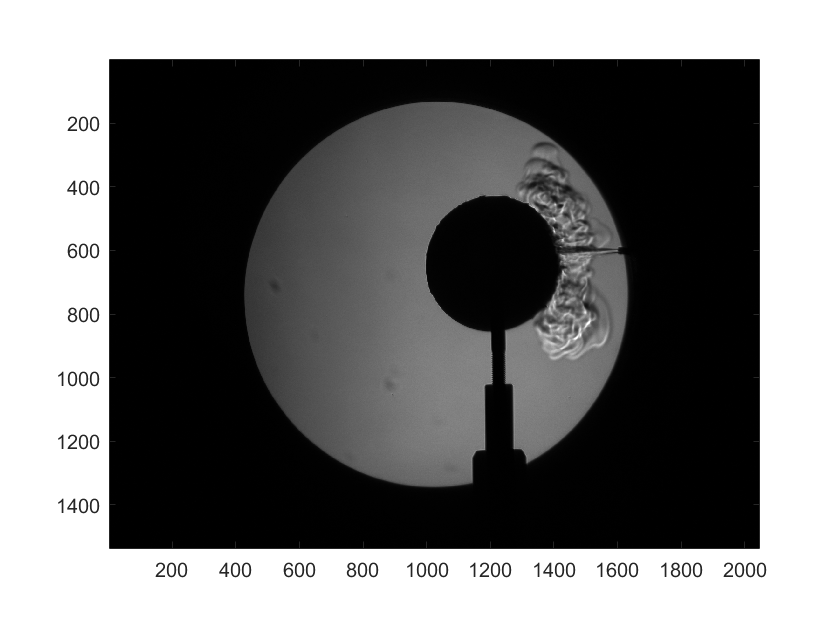

Im1=double(Im1);
Im2=double(Im2);

if (index_region == 1)
    imagesc(uint8(Im1));
    colormap(gray);
    axis image;

    xy=ginput(2);
    x1=floor(min(xy(:,1)));
    x2=floor(max(xy(:,1)));
    y1=floor(min(xy(:,2)));
    y2=floor(max(xy(:,2)));
    I1=double(Im1(y1:y2,x1:x2)); 
    I2=double(Im2(y1:y2,x1:x2));
elseif (index_region == 0)
    I1=Im1;
    I2=Im2;
end


I1_original=I1;
I2_original=I2;

## correcting the global and local intensity change in images

[m1,n1]=size(I1);
window_shifting=[1;n1;1;m1]; % [x1,x2,y1,y2] deines a rectangular window for global correction
[I1,I2]=correction_illumination(I1,I2,window_shifting,size_average);

## pre-processing for reducing random noise,

## and downsampling images if displacements are large

[I1,I2] = pre_processing_a(I1,I2,scale_im,size_filter);

I_region1=I1;
I_region2=I2;

## initial optical flow calculation for a coarse-grained velocity field

## (ux0,uy0)

[ux0,uy0,vor,ux_horn,uy_horn,error1]=OpticalFlowPhysics_fun(I_region1,I_region2,lambda_1,lambda_2);
% ux is the velocity (pixels/unit time) in the image x-coordinate (from the left-up corner to right)
% uy is the velocity (pixels/unit time) in the image y-coordinate (from the left-up corner to bottom)

## generate the shifted image from Im1 based on the initial coarse-grained velocity field (ux0, uy0),

## and then calculate velocity difference for iterative correction

Im1=uint8(I1_original);
Im2=uint8(I2_original);

ux_corr=ux0;
uy_corr=uy0;

## estimate the displacement vector and make correction in iterations

k=1;
while k<=no_iteration
    [Im1_shift,uxI,uyI]=shift_image_fun_refine_1(ux_corr,uy_corr,Im1,Im2);
    
    I1=double(Im1_shift);
    I2=double(Im2);
    
    size_filter_1=2;
    [I1,I2] = pre_processing_a(I1,I2,1,size_filter_1);
    
    % calculation of correction of the optical flow 
    [dux,duy,vor,dux_horn,duy_horn,error2]=OpticalFlowPhysics_fun(I1,I2,lambda_1,lambda_2);

    % refined optical flow
    ux_corr=uxI+dux;
    uy_corr=uyI+duy;
    
    
    k=k+1;
end

## refined velocity field

ux=ux_corr;    %%%%%
uy=uy_corr;    %%%%%

## show the images and processed results

## plot the images, velocity vector, and streamlines in the initail and

## refined estimations

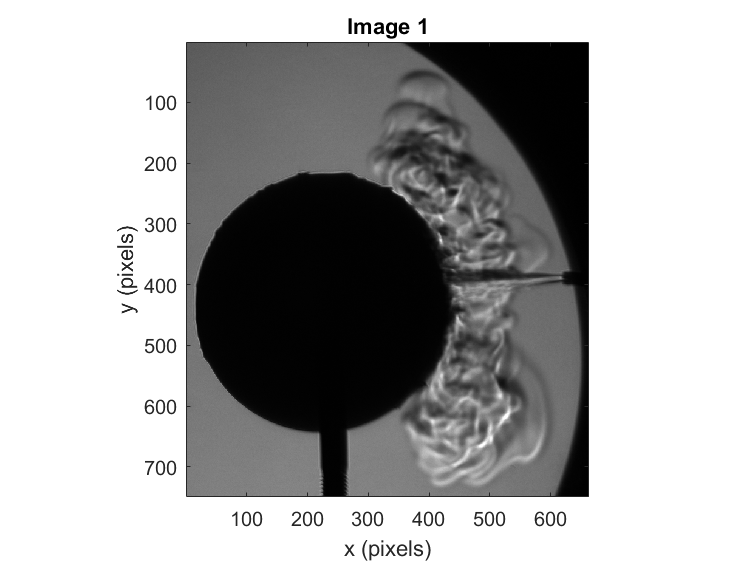

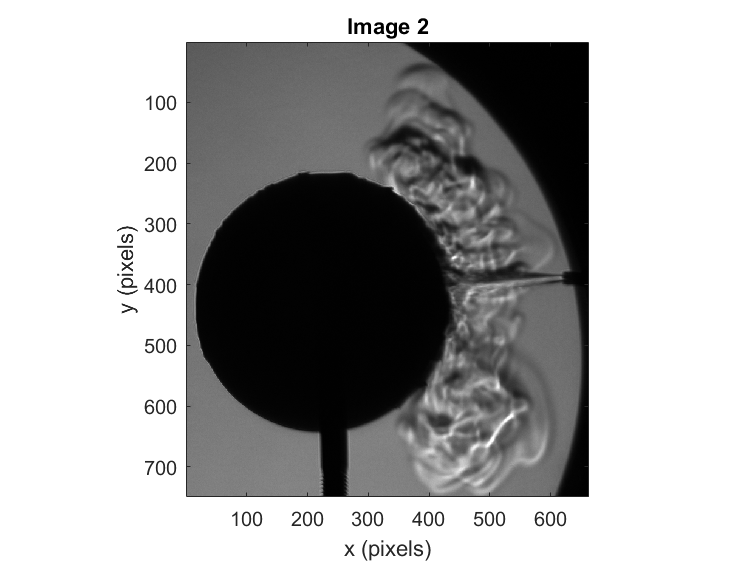

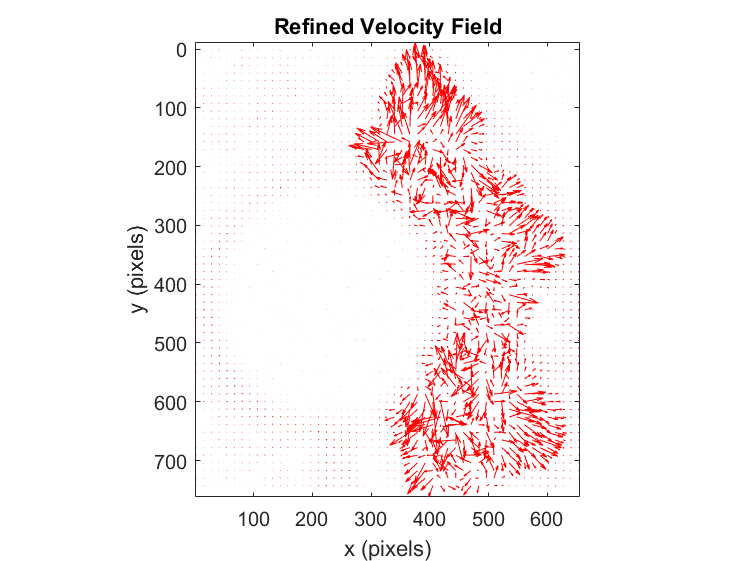

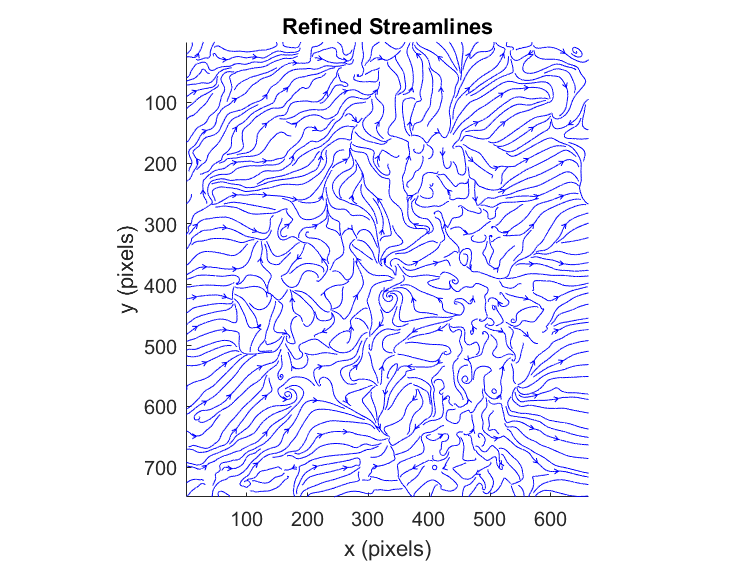

plots_set_1;

## plot the fields of velocity magnitude, vorticity and the second invariant Q

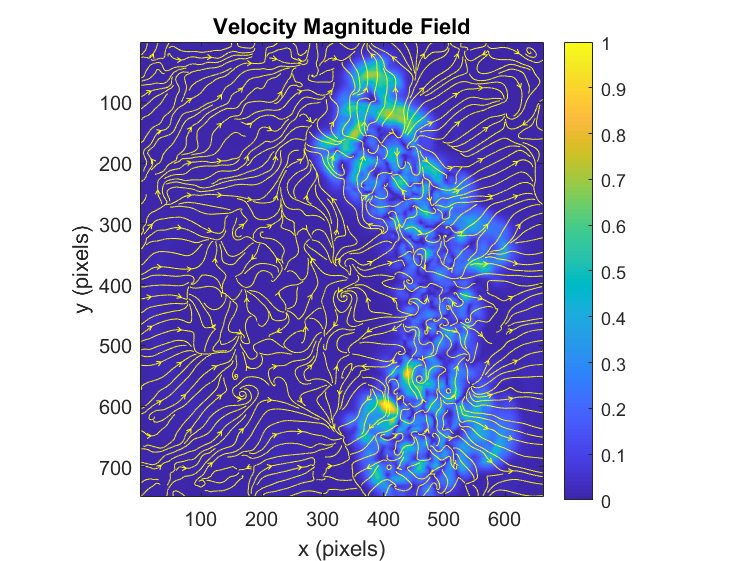

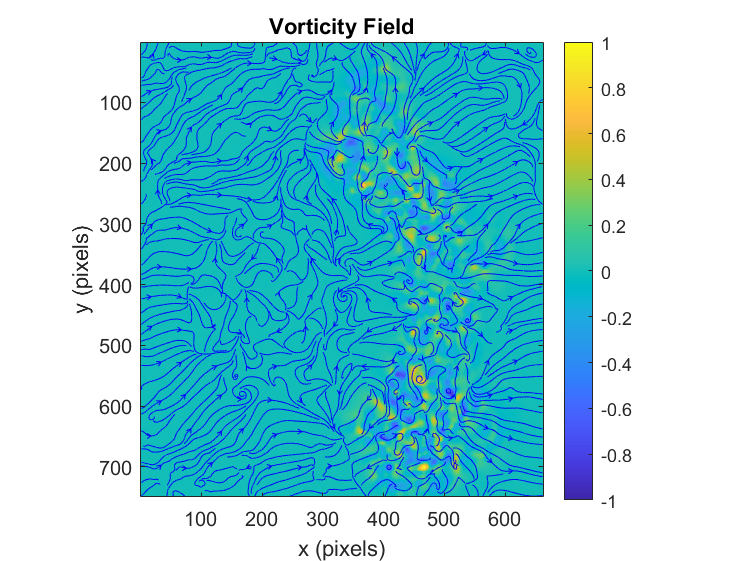

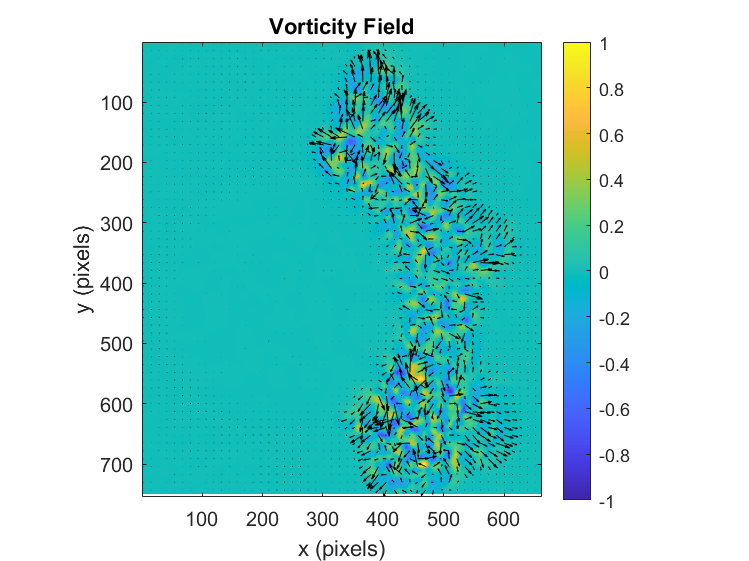

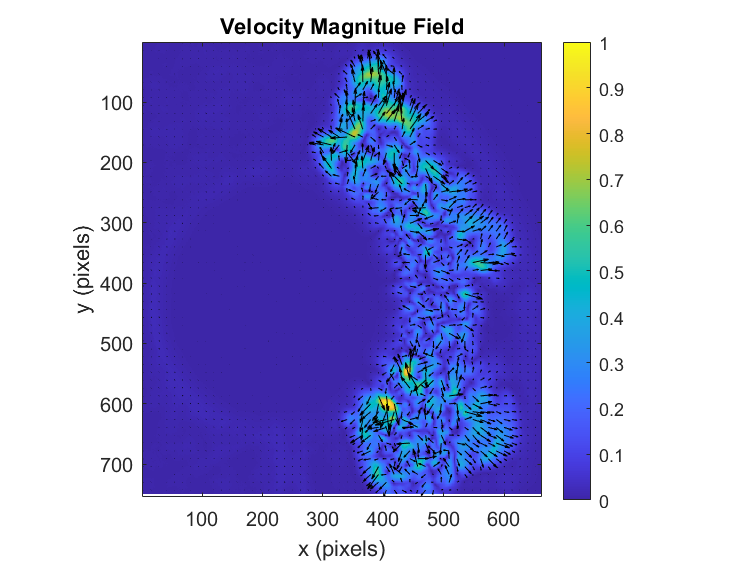

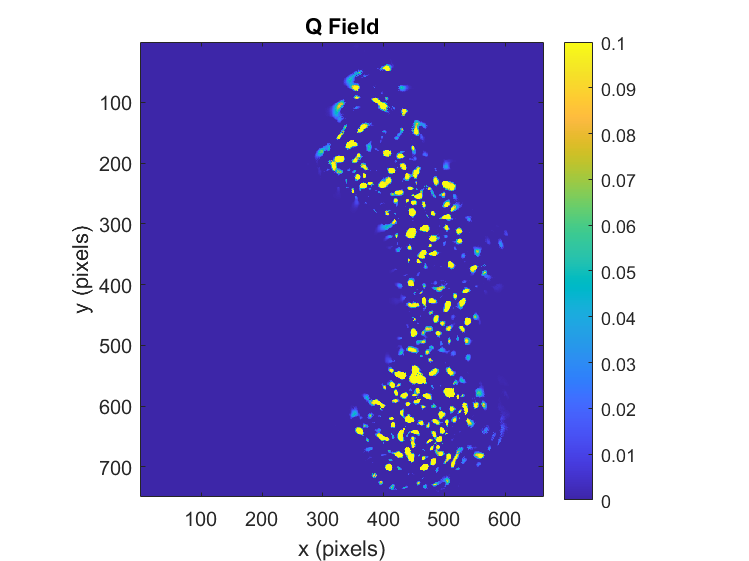

plots_set_2;